# **META 2**

10. Carregue a estrutura de dados guardada no último ponto da meta anterior.

dados = load("dados.mat").dados;

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    tamanhoSinal    fimAudio    taxaCruzamentoZeros    energiaTotal    tAmplitudeMaxima    razaoAmplitude    desvioPadrao
    ______________________    _______________    ____________    ______    _________    ________________    ______________    ____________    ________    ___________________    ____________    ________________    ______________    ____________

    {'audios\0_33_0.wav' }    {'0_3

11. Para cada sinal obtido após o pré-processamento, determine os coeficientes da série complexa de Fourier e guarde na estrutura de dados do ponto anterior.

for i = 1:length(dados)
    sinal = dados(i).sinal;
    tamanhoSinal = length(sinal);
    
    % Zero-padding na FFT para melhor resolução de frequência
    tamanhoPadding = 2^nextpow2(tamanhoSinal); 

    % Calculo da transformada com padding e com normalização 
    coeficientesFourier = fft(sinal, tamanhoPadding) / tamanhoSinal;
    
    % Calculo sem padding com e normalização
    %coeficientesFourier = fft(sinal) / tamanhoSinal;

    dados(i).coeficientesFourier = coeficientesFourier;
end


12. Calcule para cada dígito, o espectro de amplitude mediano, normalizado pelo número de amostras (i.e., equivalente ao módulo dos coeficientes da série complexa de Fourier), e somente para frequências positivas. Calcule também o primeiro quartil (25%) e terceiro quartil (75%). A Figura 4 mostra um exemplo. Compare os gráficos obtidos.

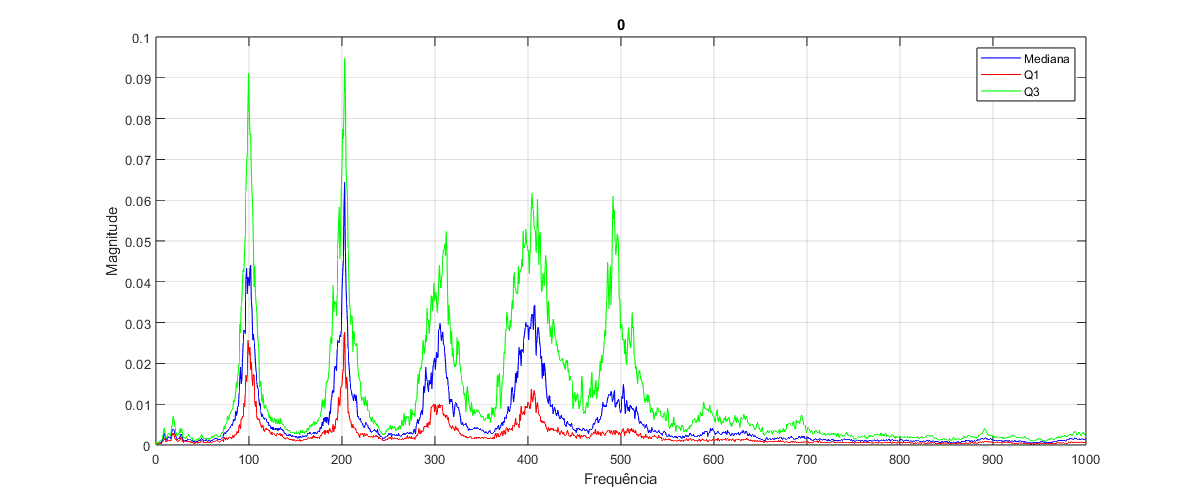

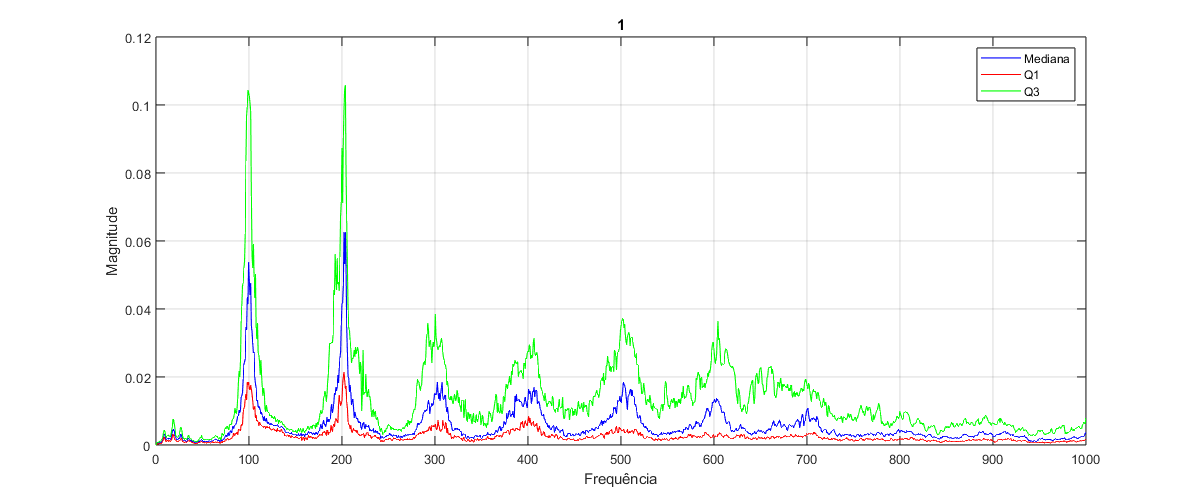

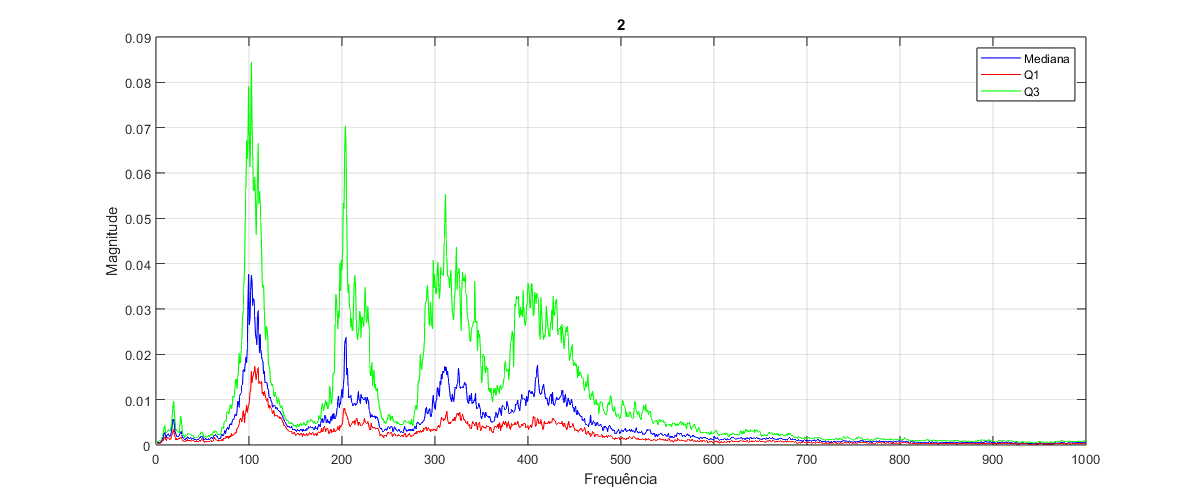

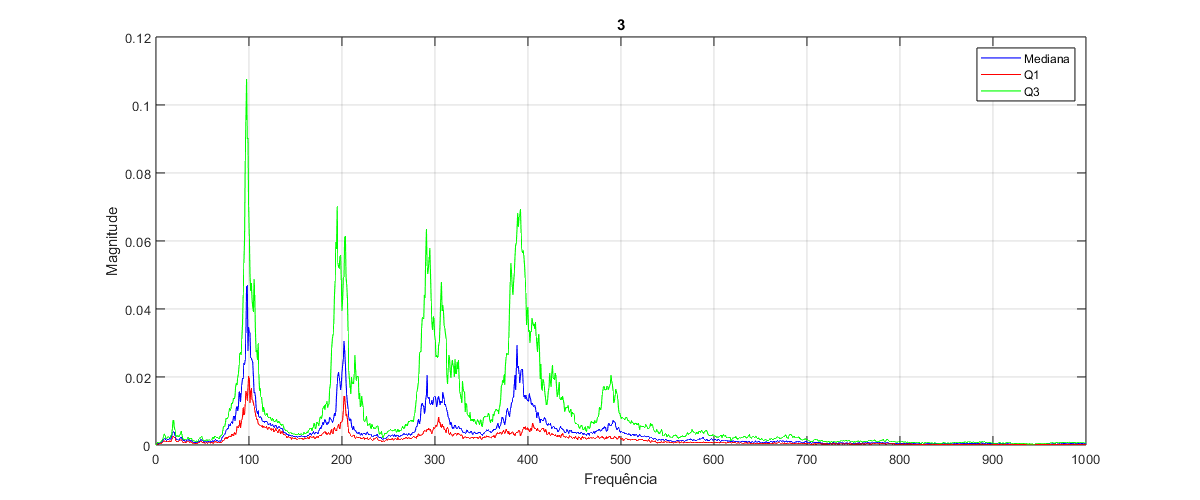

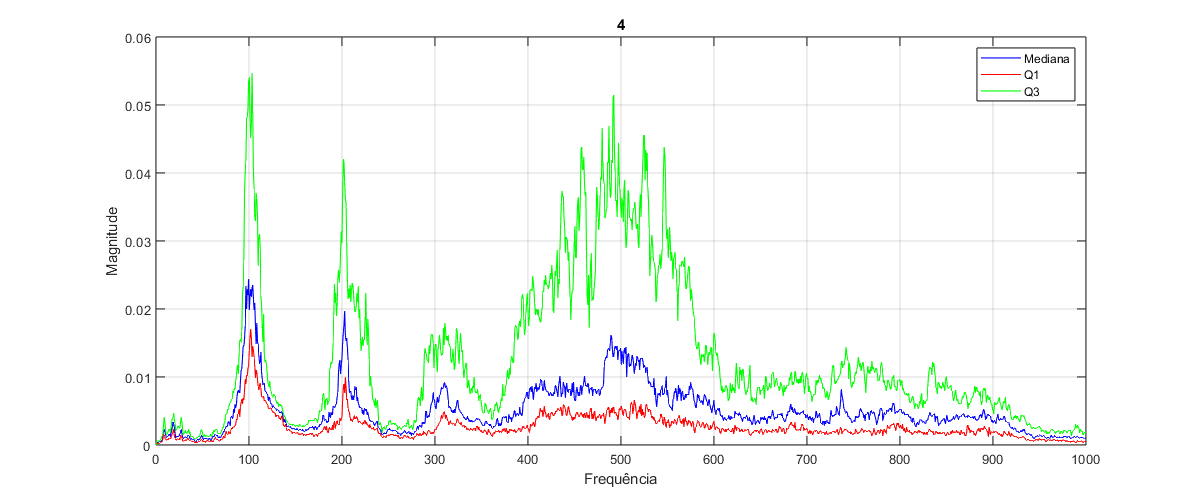

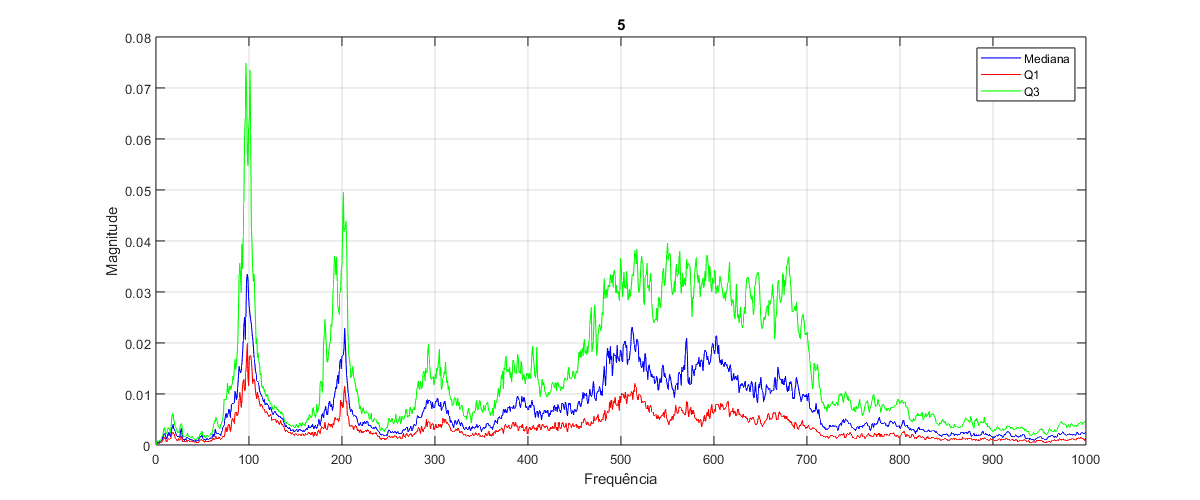

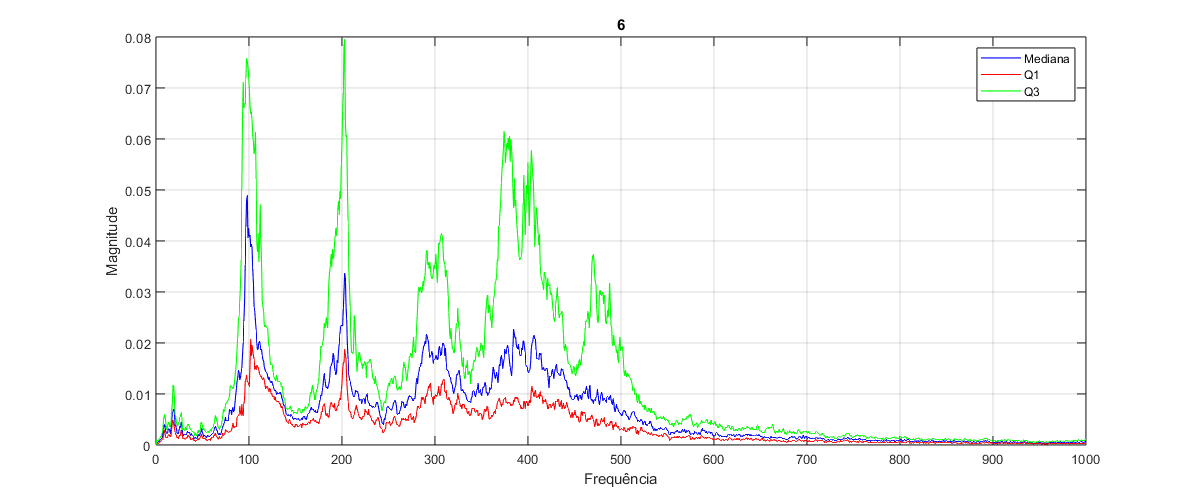

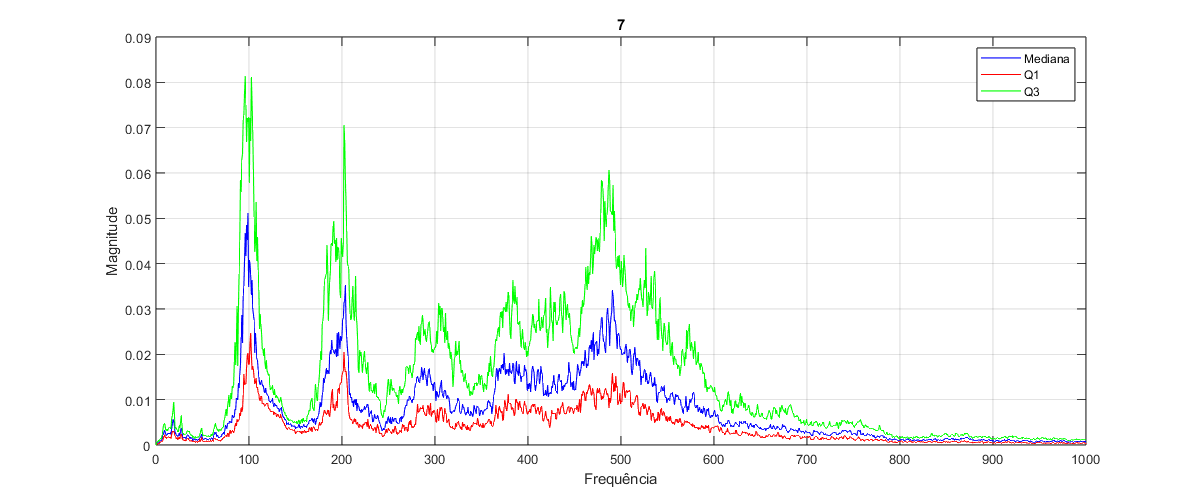

taxaAmostragem=48000;

for digito = 0:9
    indices = find([dados.digito] == digito);
    espectro= [];

    for i = indices
        coeficientesFourier = dados(i).coeficientesFourier;

        % Extrair apenas as frequências positivas (0 Hz até TaxaAmostragem/2)
        magnitudes = abs(coeficientesFourier(1:length(coeficientesFourier)/2));

        espectro = [espectro; magnitudes(:)'];
    end

    % Cálculo das estatísticas (Mediana, 1º quartil, 3º quartil)
    mediana = median(espectro, 1);
    q1 = quantile(espectro, 0.25, 1);
    q3 = quantile(espectro, 0.75, 1);

    % Criar vetor de frequências (todas as amostras têm o mesmo vetor)
    frequencias = linspace(0, taxaAmostragem / 2, length(magnitudes));

    % Plotar espectro do dígito
    figure();
    plot(frequencias, mediana, 'b'); hold on;
    plot(frequencias, q1, 'r');
    plot(frequencias, q3, 'g');
    title(digito);
    xlabel('Frequência');
    ylabel('Magnitude');
    legend('Mediana', 'Q1', 'Q3');
    xlim([0 1000]);
    set(gcf, 'Position', [100, 100, 1200, 500]);
    grid on;
end

13. Identifique e implemente o cálculo de possíveis características espectrais que permitam a diferenciação entre dígitos como: máximos espectrais (posição e amplitude), médias espectrais, spectral edge frequency, etc. Deverá efetuar o cálculo para cada áudio de pelo menos 5 características espectrais e atualizar a sua estrutura de dados.

for i = 1:length(dados)
    taxaAmostragem = dados(i).taxaAmostragem;
    coeficientesFourier = dados(i).coeficientesFourier;

    % Apenas as frequências positivas
    magnitudes = abs(coeficientesFourier(1:length(coeficientesFourier)/2));
    frequencias = linspace(0, taxaAmostragem/2, length(magnitudes));
    
    % Frequência Dominante
    indiceMaximo = find(magnitudes == max(magnitudes), 1, 'first');
    frequenciaDominante = frequencias(indiceMaximo);
    dados(i).frequenciaDominante = frequenciaDominante;
    
    % Peak to Average Ratio (PAR)
    par = max(magnitudes) / mean(magnitudes);
    dados(i).par = par;
    
    % Entropia Espectral
    espectroNormalizado = magnitudes / sum(magnitudes);  
    entropia = -sum(espectroNormalizado .* log(espectroNormalizado)); 
    dados(i).entropia = entropia;

    % Spectral Edge Frequency (SEF 90%)
    energiaTotal = sum(magnitudes.^2);
    energiaAcumulada = cumsum(magnitudes.^2);
    sef = interp1(energiaAcumulada, frequencias, 0.90 * energiaTotal, 'linear', 'extrap');
    dados(i).sef = sef;

    % Spectral Slope 
    X = [ones(length(frequencias), 1), frequencias(:)]; % Matriz de regressão
    Y = magnitudes(:);
    coef = (X' * X) \ (X' * Y); % Regressão linear
    spectralSlope = coef(2); % Coeficiente angular da reta ajustada
    dados(i).spectralSlope = spectralSlope;
end



14. Recorrendo à representação gráfica das características espectrais extraídas no ponto anterior, identifique as três características que permitem uma melhor discriminação dos dígitos. Para isto pode utilizar boxplots, gráficos 2D, 3D, etc. Indique as características escolhidas.

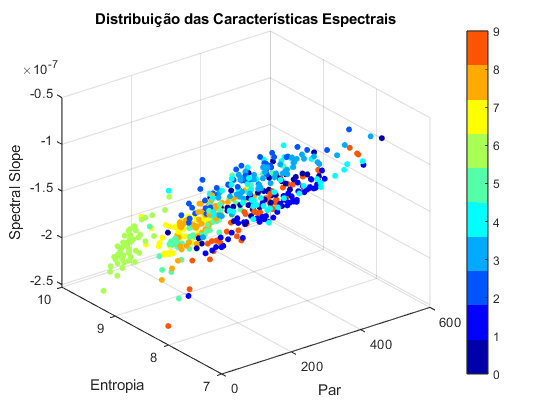

% Inicializar as caracteristicas a cruzar...
sinais = [dados.sinal];
valores1 = [dados.par];
valores2 = [dados.entropia];
valores3 = [dados.spectralSlope];
digitos = [dados.digito];

figure;
scatter3(valores1, valores2, valores3, 20, digitos, 'filled');  
xlabel('Par'); 
ylabel('Entropia'); 
zlabel('Spectral Slope');
grid on;
title('Distribuição das Características Espectrais');

colormap(jet(10));  
caxis([0 9]); 
cor = colorbar;
cor.Ticks = 0:9;  
cor.TickLabels = {'0','1','2','3','4','5','6','7','8','9'};

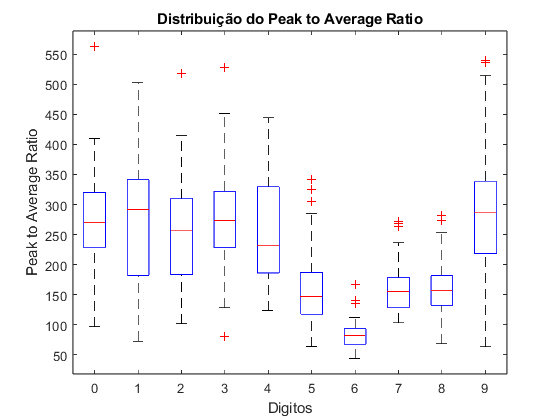

boxplot(valores1,digitos);
xlabel('Digitos');
ylabel('Peak to Average Ratio');
title('Distribuição do Peak to Average Ratio');

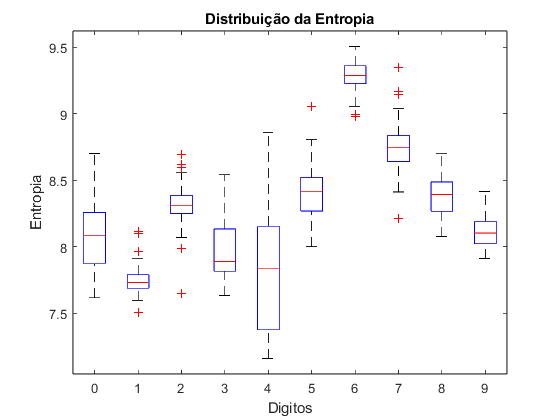


boxplot(valores2, digitos);
xlabel('Digitos');
ylabel('Entropia');
title('Distribuição da Entropia');

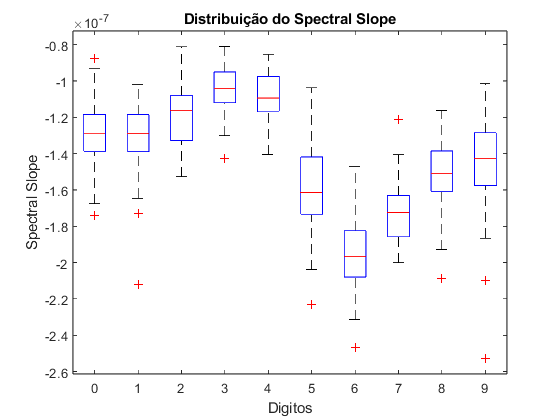


boxplot(valores3, digitos);
xlabel('Digitos');
ylabel('Spectral Slope');
title('Distribuição do Spectral Slope');

15. Atualize o ficheiro “.mat” carregado no início da meta com a estrutura de dados atualizada.

save('dados.mat',"dados")